clear all;
mode=0;
if mode == 1
    s='F:\';
else
    s='/media/zhijian/Document/';
end
pathRoundTruth='/media/zhijian/Document/grow/slam/expriment/kitti/groundTruth/00.txt';
pathEsti1='/media/zhijian/Document/grow/slam/expriment/kitti/pl_slam/origin_00.txt';
pathEsti2='/media/zhijian/Document/grow/slam/slamDataSet/KITTI/data_odometry_poses/way1/1.txt';
pathEsti3='/media/zhijian/Document/grow/slam/slamDataSet/KITTI/data_odometry_poses/my00.txt';

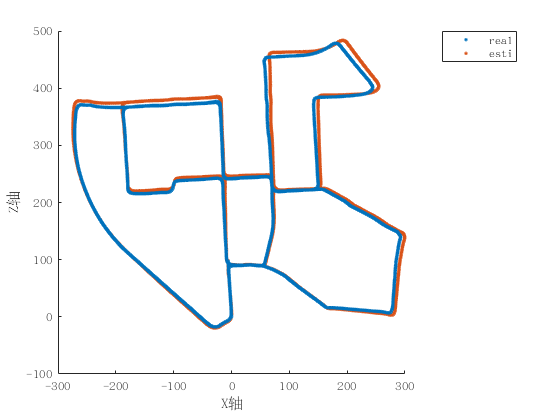

esti=textread(pathEsti1);
esti2=textread(pathEsti2);
num=length(esti);
[realT realQ realAngle]=readKitti(pathRoundTruth,1);
estiT=esti(:,[4 8 12]);
plot3(realT(1:num,1),realT(1:num,2),realT(1:num,3),'.')
hold on
plot3(estiT(:,1),estiT(:,2),estiT(:,3),'.')
view([0,0])%指定视角
legend('real','esti');
xlabel('X轴');ylabel('Y轴');zlabel('Z轴');


ATE=ateError(esti,[realT realQ])

ATE =           8.51259758064554

RE=reError(esti,[realT realQ],100)

RE =           3.46165550400897